# Plan Mobile Robot Paths Using RRT 5_9(이진혁 수정본)

This example shows how to use the rapidly exploring random tree (RRT) algorithm to plan a path for a vehicle through a known map. Special vehicle constraints are also applied with a custom state space. You can tune your own planner with custom state space and path validation objects for any navigation application. 

load("scans_12final.mat")

다음 사용 중 오류가 발생함: load
파일 또는 디렉터리 'scans_12final.mat'을(를) 찾을 수 없습니다.

% maxRange = 12; % meters
% resolution = 20; % cells per meter
% 
% slamObj = lidarSLAM(resolution,maxRange);
% slamObj.LoopClosureThreshold = 360;
% slamObj.LoopClosureSearchRadius = 8;
% 
% for i = 1:numel(scans)
% 
%     addScan(slamObj,scans{i});
% 
%     if rem(i,10) == 0
%         show(slamObj);
%     end
% end
% 
% [scansSLAM,poses] = scansAndPoses(slamObj);
% deepracerMap = buildMap(scansSLAM,poses,resolution,maxRange);
% figure
% show(deepracerMap)
% title('Occupancy Map of deepracer')

%실행시간단축을 위해 주석처리해둠 미리 fig파일과 gridmap으로 저장해둠 저장해뒀음

## Load Occupancy Map

Load an existing occupancy map of a small office space. Plot the start and goal poses of the vehicle on top of the map.

%load("office_area_gridmap.mat","occGrid")
load("12f_final_deepracerMAP.mat","deepracerMap")


occGrid=deepracerMap;
%아 멍청했다 그냥 map에도 넣어줄걸
map= deepracerMap

map =   occupancyMap - 속성 있음:

   mapLayer Properties
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
                LayerName: 'probabilityLayer'
                 DataType: 'double'
             DefaultValue: 0.5000
      GridLocationInWorld: [-15.4596 -12]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [-15.4596 -12]
               Resolution: 20
                 GridSize: [780 760]
             XLocalLimits: [0 38]
             YLocalLimits: [0 39]
             XWorldLimits: [-15.4596 22.5404]
             YWorldLimits: [-12 27]


% 2D_Grid Map의 좌측상단에 있는'저장' 버튼을 이용해 작업경로에 fig 파일로 저장해야 함

fig = openfig('12f_ori.fig','visible'); % fig 파일 지정

[xi,yi] = getpts(fig); % 해당 fig 파일을 불러옴 
start = [xi,yi, -pi]; % 해당 fig 파일에서 지점을 클릭 후 Enter를 누르면 point 지정 완료

[xj,yj] = getpts(fig); % 해당 fig 파일을 불러옴
goal = [xj,yj, 0];  % 해당 fig 파일에서 지점을 클릭 후 Enter를 누르면 point 지정 완료


disp(start); % 설정한 start_point의 좌표값 출력

   -2.3020   13.9115   -3.1416



disp(goal); % 설정한 end_point의 좌표값 출력

   10.9762    1.7714         0



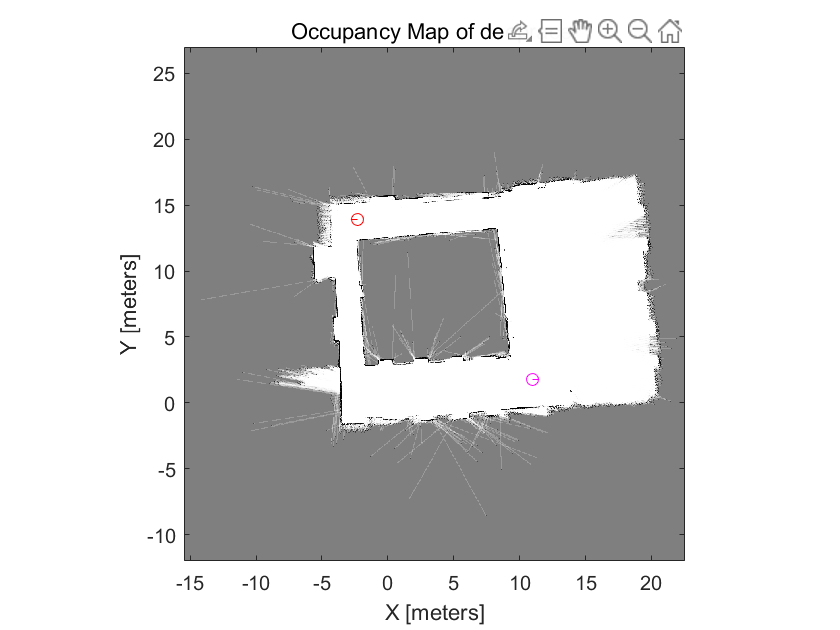

 

% Show start and goal positions of robot.
hold on
plot(start(1),start(2),'ro')
plot(goal(1),goal(2),'mo')

% Show start and goal headings.
r = 0.5;
plot([start(1),start(1) + r*cos(start(3))],[start(2),start(2) + r*sin(start(3))],'r-')
plot([goal(1),goal(1) + r*cos(goal(3))],[goal(2),goal(2) + r*sin(goal(3))],'m-')
hold off

## Define State Space

Specify the state space of the vehicle using a `stateSpaceDubins` object and specifying the state bounds. This object limits the sampled states to feasible Dubins curves for steering a vehicle within the state bounds. A turning radius of 0.4 meters allows for tight turns in this small environment.

bounds = [occGrid.XWorldLimits; occGrid.YWorldLimits; [-pi pi]];

ss = stateSpaceDubins(bounds); % ss = stateSpaceSE2; %으로 교체해보기
ss.MinTurningRadius = 0.4;

## Plan The Path

To plan a path, the RRT algorithm samples random states within the state space and attempts to connect a path. These states and connections need to be validated or excluded based on the map constraints. The vehicle must not collide with obstacles defined in the map.

Create a `validatorOccupancyMap` object with the specified state space. Set the `Map` property to the loaded `occupancyMap` object. Set a `ValdiationDistance` of 0.05 m. This validation distance discretizes the path connections and checks obstacles in the map based on this.

stateValidator = validatorOccupancyMap(ss); 
stateValidator.Map = occGrid;
stateValidator.ValidationDistance = 0.05;

Create the path planner and increase the max connection distance to connect more states. Set the maximum number of iterations for sampling states.

planner = plannerRRT(ss,stateValidator);
planner.MaxConnectionDistance = 2.0;
planner.MaxIterations = 30000;

Customize the `GoalReached` function. This example helper function checks if a feasible path reaches the goal within a set threshold. The function returns `true` when the goal has been reached, and the planner stops.

planner.GoalReachedFcn = @exampleHelperCheckIfGoal;

Plan the path between the start and goal. Reset the random number generator for reproducible results.

rng default

[pthObj, solnInfo] = plan(planner,start,goal);

## Plot the Path

Show the occupancy map. Plot the search tree from the `solnInfo`. Interpolate and overlay the final path.

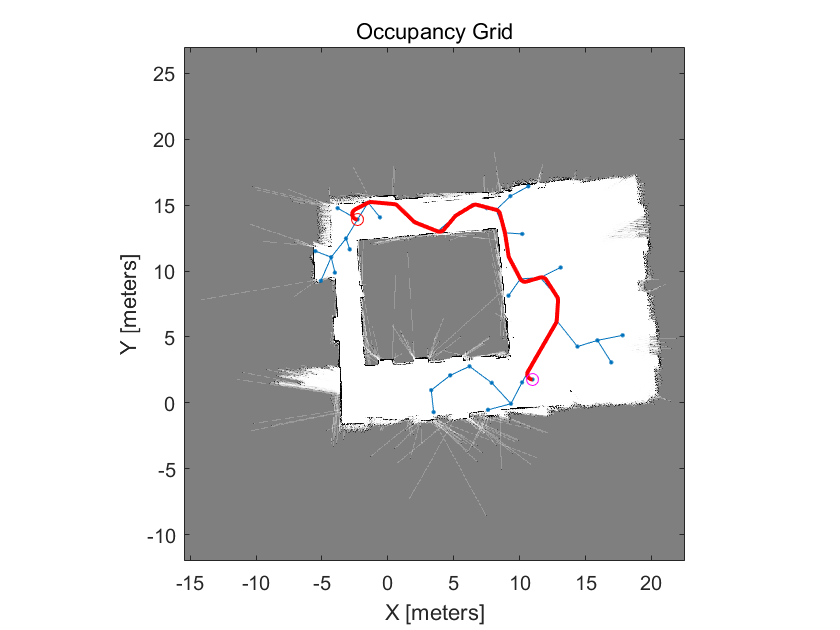

show(occGrid)
hold on

% Plot entire search tree.
plot(solnInfo.TreeData(:,1),solnInfo.TreeData(:,2),'.-');

% Interpolate and plot path.
interpolate(pthObj,300)
plot(pthObj.States(:,1),pthObj.States(:,2),'r-','LineWidth',2)

% Show start and goal in grid map.
plot(start(1),start(2),'ro')
plot(goal(1),goal(2),'mo')
hold off

## Customize Dubins Vehicle Constraints

To specify custom vehicle constraints, customize the state space object. This example uses `ExampleHelperStateSpaceOneSidedDubins`, which is based on the `stateSpaceDubins` class. This helper class limits the turning direction to either right or left based on a Boolean property, `GoLeft`. This property essentially disables path types of the `dubinsConnection` object.

Create the state space object using the example helper. Specify the same state bounds and give the new Boolean parameter as `true` (left turns only).

% Only making left turns
goLeft = true;

% Create the state space
ssCustom = ExampleHelperStateSpaceOneSidedDubins(bounds,goLeft);
ssCustom.MinTurningRadius = 0.4;

%흠 이거 조금 수정해봄
ss = stateSpaceSE2;

## Plan Path

Create a new planner object with the custom Dubins constraints and a validator based on those constraints. Specify the same `GoalReached` function.

stateValidator2 = validatorOccupancyMap(ss);  %(ssCustom); %에서 변경
stateValidator2.Map = occGrid;
stateValidator2.ValidationDistance = 0.05; %0.05에서 변경

planner = plannerRRT(ss,stateValidator2); %ssCustom ->ss
%planner.ContinueAfterGoalReached = true;

planner.MaxConnectionDistance = 1; 
planner.MaxIterations = 30000;
planner.GoalReachedFcn = @exampleHelperCheckIfGoal;

Plan the path between the start and goal. Reset the random number generator again.

rng default
%rng(100, 'twister') % repeatable result

[pthObj2,solnInfo] = plan(planner,start,goal);

## Plot Path

Draw the new path on the map. The path should only execute left turns to reach the goal.

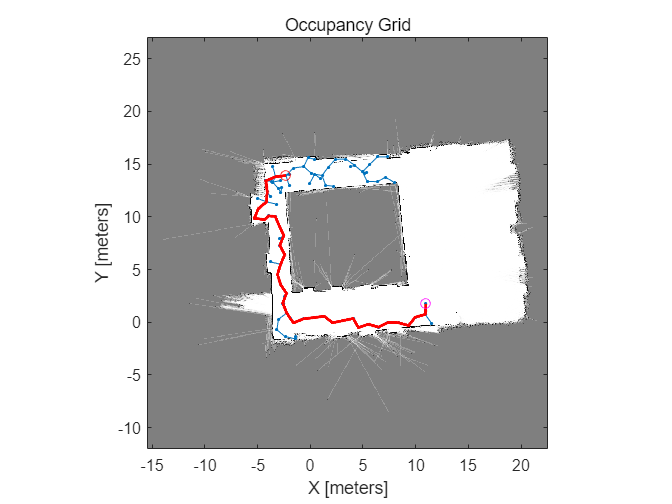

figure
show(occGrid)

hold on

% Show the search tree.
plot(solnInfo.TreeData(:,1),solnInfo.TreeData(:,2),'.-');

% Interpolate and plot path.
pthObj2.interpolate(3000) %원래 300
plot(pthObj2.States(:,1), pthObj2.States(:,2), 'r-', 'LineWidth', 2) % 코드추가이후 길을 잘 못찾는거 같음? 일단 수정해서 굴러감

% Show start and goal in grid map.
plot(start(1), start(2), 'ro')
plot(goal(1), goal(2), 'mo')
hold off

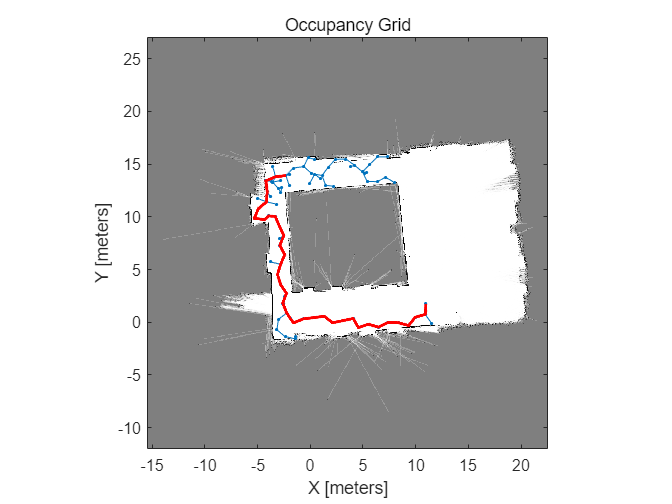

deepracerMap.show;
hold on;
plot(solnInfo.TreeData(:,1),solnInfo.TreeData(:,2), '.-'); % tree expansion
plot(pthObj2.States(:,1),pthObj2.States(:,2),'r-','LineWidth',2); % draw path

## 그 뭐시기냐 로봇 pathfollowing임 PRM pathplanning을 사용함

## Define Waypoints

Define a set of waypoints for the desired path for the robot

path = pthObj2.States(:,1:2); %이전에 나온 결과를 이용해서 path 만들꺼임 : 전체 /1:2 1행,2행자료 -> 1행2행 전체자료를 가져오겟다

Set the current location and the goal location of the robot as defined by the path. 시작위치와 도착지점 정하기.

robotInitialLocation = path(1,:); %1번째, 행전체 
robotGoal = path(end,:);

Assume an initial robot orientation (the robot orientation is the angle between the robot heading and the positive X-axis, measured counterclockwise).

초기 로봇 방향을 가정합니다(로봇 방향은 시계 반대 방향으로 측정된 로봇 방향과 양의 X축 사이의 각도입니다). 

initialOrientation = 0; 

Define the current pose for the robot [x y theta] 현재위치 설정 x,y,theta

robotCurrentPose = [robotInitialLocation initialOrientation]'; %로봇 시작지점이랑, 초기방향을 묶음

## Create a Kinematic Robot Model 

Initialize the robot model and assign an initial pose. The simulated robot has kinematic equations for the motion of a two-wheeled differential drive robot. The inputs to this simulated robot are linear and angular velocities.

로봇 모델을 초기화하고 초기 포즈를 할당합니다. 시뮬레이션된 로봇에는 2륜 차동 구동 로봇의 운동에 대한 운동 방정식이 있습니다. 이 시뮬레이션 로봇에 대한 입력은 선형 및 각속도입니다.

robot = differentialDriveKinematics("TrackWidth", 1, "VehicleInputs", "VehicleSpeedHeadingRate");



Visualize the desired path  / path 보기

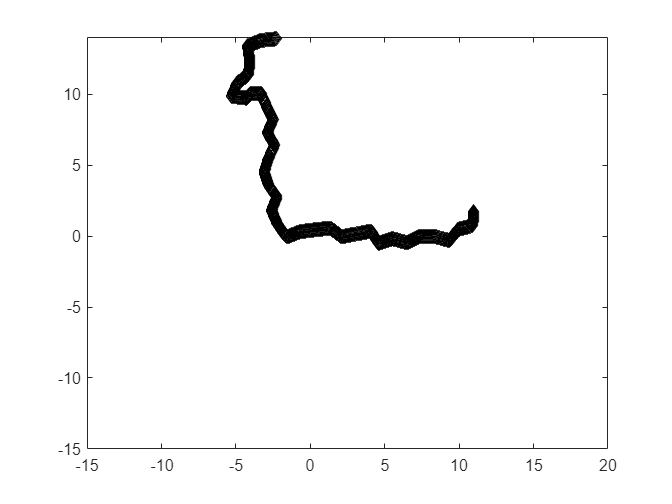

figure

plot(pthObj2.States(:,1), pthObj2.States(:,2),'k--d') 
xlim([-15 20])
ylim([-15 14])

## Define the Path Following Controller

Based on the path defined above and a robot motion model, you need a path following controller to drive the robot along the path. Create the path following controller using the [`controllerPurePursuit`](docid:robotics_ref.buoofp1-1) object. 

위에서 정의한 경로와 로봇 모션 모델을 기반으로 경로를 따라 로봇을 구동하려면 컨트롤러를 따라가는 경로가 필요합니다. controllerPurePursuit 개체를 사용하여 컨트롤러 다음 경로를 만듭니다.

controller = controllerPurePursuit;
%controller = mpc;

%controllerPurePursuit 웨이포인트 집합을 따라 컨트롤러 만들기

Use the path defined above to set the desired waypoints for the controller

컨트롤러에 대해 원하는 웨이포인트를 설정하려면 위에 정의된 경로를 사용하십시오.

controller.Waypoints = path; %기존에 나온 결과를 웨이포인트삼음
%controller.= path;

Set the path following controller parameters. The desired linear velocity is set to 0.6 meters/second for this example.

컨트롤러 매개변수에 따라 경로를 설정합니다. 이 예시에서 원하는 선형 속도는 0.6미터/초로 설정됩니다.

controller.DesiredLinearVelocity = 0.6;

The maximum angular velocity acts as a saturation limit for rotational velocity, which is set at 2 radians/second for this example.

최대 각속도는 회전 속도에 대한 포화 한계로 작용하며, 이 예에서는 초당 2라디안으로 설정됩니다.

controller.MaxAngularVelocity = 2;

As a general rule, the lookahead distance should be larger than the desired linear velocity for a smooth path. The robot might cut corners when the lookahead distance is large. In contrast, a small lookahead distance can result in an unstable path following behavior. A value of 0.3 m was chosen for this example.

일반적으로 예견 거리는 부드러운 경로를 위해 원하는 선형 속도보다 커야 합니다. 예견 거리가 크면 로봇이 코너를 잘릴 수 있습니다. 대조적으로, 작은 미리보기 거리는 동작을 따르는 불안정한 경로를 초래할 수 있습니다. 이 예에서는 0.3m 값이 선택되었습니다.

controller.LookaheadDistance = 0.3;

You can compute the `path` using the PRM path planning algorithm. See  [Path Planning in Environments of Different Complexity](docid:robotics_ug.mw_04f9e096-7491-4efd-8380-9d7e178f95b6) for details.

PRM 경로 계획 알고리즘을 사용하여 경로를 계산할 수 있습니다. 자세한 내용은 복잡성이 다른 환경에서의 경로 계획을 참조하십시오.

mapInflated = copy(map);
inflate(mapInflated, robot.TrackWidth/2);
prm = robotics.PRM(mapInflated);

% robotics. 뒤에 gazebo있던데 사용할수 있을지도?
%prm = robotics.RRT %
%https://theclassytim.medium.com/robotic-path-planning-rrt-and-rrt-212319121378
%RRT나 RRT*사용하려면 참고???
prm.NumNodes = 100;
prm.ConnectionDistance = 10;

Find a path between the start and end location. Note that the `path` will be different due to the probabilistic nature of the PRM algorithm.

시작 위치와 끝 위치 사이의 경로를 찾습니다. 경로는 PRM 알고리즘의 확률적 특성으로 인해 달라집니다.

startLocation = start(1:2);%[4.0 2.0];%위에서 얻은 start를 넣어줌 2d라서 x,y 좌표만 필요함
endLocation = goal(1:2);%[24.0 20.0]; %위에서 얻은 goal을 넣어줌 2d라서 x,y 좌표만 필요함
path = findpath(prm, startLocation, endLocation)

path =    -2.3020   13.9115
   -2.5602   13.5545
   -0.5785   13.6397
    8.0561   14.1630
   10.8621   12.4704
   10.5406    8.3991
    9.9994    2.3908
   10.9762    1.7714


Display the inflated map, the road maps, and the final path.

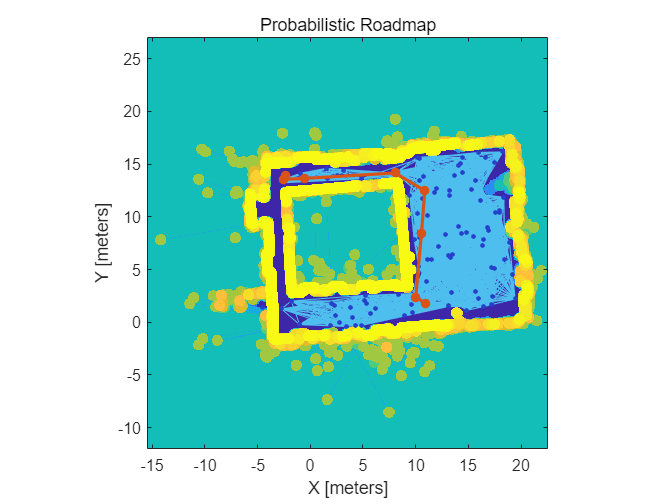

show(prm);

You defined a path following controller above which you can re-use for computing the control commands of a robot on this map. To re-use the controller and redefine the waypoints while keeping the other information the same, use the `release` function.

이 맵에서 로봇의 제어 명령을 계산하는 데 재사용할 수 있는 컨트롤러를 따라가는 경로를 정의했습니다. 컨트롤러를 재사용하고 다른 정보를 동일하게 유지하면서 웨이포인트를 재정의하려면 해제 기능을 사용하십시오.

release(controller);
controller.Waypoints = path;

## Using the Path Following Controller, Drive the Robot over the Desired Waypoints

The path following controller provides input control signals for the robot, which the robot uses to drive itself along the desired path.

경로 추종 제어기는 로봇에 대한 입력 제어 신호를 제공하며 로봇이 원하는 경로를 따라 스스로를 운전하는 데 사용합니다.

Define a goal radius, which is the desired distance threshold between the robot's final location and the goal location. Once the robot is within this distance from the goal, it will stop. Also, you compute the current distance between the robot location and the goal location. This distance is continuously checked against the goal radius and the robot stops when this distance is less than the goal radius.

로봇의 최종 위치와 목표 위치 사이의 원하는 거리 임계값인 목표 반경을 정의합니다. 로봇이 목표에서 이 거리 내에 있으면 정지합니다. 또한 로봇 위치와 목표 위치 사이의 현재 거리를 계산합니다. 이 거리는 목표 반경에 대해 지속적으로 확인되며 이 거리가 목표 반경보다 작으면 로봇이 멈춥니다.

Note that too small value of the goal radius may cause the robot to miss the goal, which may result in an unexpected behavior near the goal.

목표 반경 값이 너무 작으면 로봇이 목표를 놓치게 되어 목표 근처에서 예기치 않은 동작이 발생할 수 있습니다.

goalRadius = 0.15; %목표반경
distanceToGoal = norm(robotInitialLocation - robotGoal); %(현재시작위치- 로봇목적지)벡터의 거리

The [`controller`](docid:robotics_ref.buoofp1-1) object computes control commands for the robot. Drive the robot using these control commands until it reaches within the goal radius. If you are using an external simulator or a physical robot, then the controller outputs should be applied to the robot and a localization system may be required to update the pose of the robot. The controller runs at 10 Hz.

컨트롤러 개체는 로봇에 대한 제어 명령을 계산합니다. 목표 반경 내에 도달할 때까지 이러한 제어 명령을 사용하여 로봇을 구동합니다. 외부 시뮬레이터 또는 물리적 로봇을 사용하는 경우 컨트롤러 출력을 로봇에 적용해야 하며 로봇의 포즈를 업데이트하기 위해 로컬라이제이션 시스템이 필요할 수 있습니다. 컨트롤러는 10Hz에서 실행됩니다.

% % Initialize the simulation loop
% sampleTime = 0.1;
% vizRate = rateControl(1/sampleTime);  %->10Hz
% %ratecontrol->고정 주파수에서 루프 실행
% %개체를 사용하면 고정 된 주파수에서 루프를 실행할 수 있습니다. 또한 루프 반복의 타이밍에 대한 통계를 수집합니다.
% %루프에서 waitfor를 사용하여 다음 단계까지 코드 실행을 일시 중지합니다. 닫힌 코드가 작동하는 데 시간이 오래 걸리지 않는 한 루프는 매 초마다 작동합니다.
% %개체는 속성을 사용하여 루프 작업 시간을 연장하는 방법을 결정합니다. 기본 설정은 루프보다 큰 경우 루프를 즉시 실행합니다. 사용으로 인해 대기 중지 메서드는 다음 루프를 실행하기 위해 다음 배수에 도달할 때까지 기다립니다.
% 
% 
% % Initialize the figure
% figure
% 
% % Determine vehicle frame size to most closely represent vehicle with plotTransforms 
% %차량프레임 크기 설정
% frameSize = robot.TrackWidth/0.8;
% 
% while( distanceToGoal > goalRadius )  %목표반경보다 작을때까지 반복
%     
%     % Compute the controller outputs, i.e., the inputs to the robot
%     %컨트롤러 출력, 즉 로봇에 대한 입력을 계산합니다.
%     [v, omega] = controller(robotCurrentPose);
%     %[vel,angvel] = controller(pose) -> 컨트롤러(pose)는 차량의 위치와 방향을 처리하고 선형 속도, 및 각 속도, 출력한다.posevelangvel
%     %v는 초당 미터의 선형속도 andgle은 초당 라디안 각도속도
%     
%     % Get the robot's velocity using controller inputs
%     %컨트롤러 입력을 사용하여 로봇의 속도 가져오기
%     vel = derivative(robot, robotCurrentPose, [v omega]);
%     %stateDot = derivative(motionModel,state,cmds) 차량 상태의 시간 유도체 (모델,상태,cmds) cmds->모션 모델에 대한 입력 명령은 모션 모델에 종속되는 2요소 벡터로 지정됩니다.
%     %state derivative, 스테이트닷을 3요소 벡터[xDot yDot thetaDot]로 반환하며, 모션 모델은 자전거동, 차등동동학, 또는 외발사이클키네매틱스 오브젝트인 경우.
%     %모션 모델이 ackermannKinematics 개체인 경우 4요소 벡터[xDot yDot thetaDot psiDot]로 반환됩니다. xDot 및 yDot는 초당 미터로 지정된 차량 속도를 참조합니다. 세타닷은 차량 헤딩의 각 속도이며 psiDot는 초당 라디언스로 지정된 차량 스티어링의 각 속도입니다.state
%     %doc derivativ %참고
% 
% 
%     %
%     
%     
%     % Update the current pose
%     robotCurrentPose = robotCurrentPose + vel*sampleTime;  %현위치 업데이트 -> 현재위치+ 샘플타임x방향정보   샘플타임 설정을 변경하면 좀더 모양 변경이 가능하려나?
%     
%     % Re-compute the distance to the goal
%     distanceToGoal = norm(robotCurrentPose(1:2) - robotGoal(:)); %목표사이 거리 업데이트 로봇의 현위치의x,y좌표, 목표의 xy좌표
%     
%     % Update the plot
%     hold off
%     
%     % Plot path each instance so that it stays persistent while robot mesh moves
%     % 로봇이 움직이는 동안 지속되도록 각 인스턴스의 경로를 플로팅합니다.
%     plot(path(:,1), path(:,2),"k--d")
%     hold all
%     
%     % Plot the path of the robot as a set of transforms
%     plotTrVec = [robotCurrentPose(1:2); 0];
%     plotRot = axang2quat([0 0 1 robotCurrentPose(3)]); %axang2quat축 각도 회전을 쿼터니언(3차원에서 회전을 표현할때 사용하는 수학적 개념)으로 변환
%     plotTransforms(plotTrVec', plotRot, "MeshFilePath", "groundvehicle.stl", "Parent", gca, "View","2D", "FrameSize", frameSize);
%     light;
%     xlim([-15 20]) %맵에서 안보여서 변경함 다른 지도도 보려면 이거값 수정해야할거임
%     ylim([-15 14]) %위와동일
%     
%     waitfor(vizRate);
% end

## Create a Kinematic Robot Model

Initialize the robot model and assign an initial pose. The simulated robot has kinematic equations for the motion of a two-wheeled differential drive robot. The inputs to this simulated robot are linear and angular velocities.

로봇 모델을 초기화하고 초기 포즈를 지정합니다. 시뮬레이션된 로봇에는 2륜 차동 구동 로봇의 운동에 대한 운동 방정식이 있습니다. 이 시뮬레이션 로봇에 대한 입력은 선형 및 각속도입니다.

robot = differentialDriveKinematics("TrackWidth", 0.3, "VehicleInputs", "VehicleSpeedHeadingRate"); %track Width 뒤에 숫자가 트랙의 넓이 설정인듯 기본이 1이라서 너무 커서 0.3으로 설정함

Visualize the desired path

%figure
%plot(path(:,1), path(:,2),'k--d')
%xlim([0 13])
%ylim([0 13])

mapInflated = copy(map);
inflate(mapInflated, robot.TrackWidth/2);
prm = robotics.PRM(mapInflated);
prm.NumNodes = 100;
prm.ConnectionDistance = 10;

Find a path between the start and end location. Note that the `path` will be different due to the probabilistic nature of the PRM algorithm.

시작 위치와 끝 위치 사이의 경로를 찾습니다. 경로는 PRM 알고리즘의 확률적 특성으로 인해 달라집니다.

startLocation =  start(1:2); %[4.0 2.0];  %위에서 얻은 start를 넣어줌 2d라서 x,y 좌표만 필요함
endLocation = goal(1:2); % [24.0 20.0];
%path = findpath(prm, startLocation, endLocation)
path = findpath(prm, startLocation, endLocation)

path =    -2.3020   13.9115
   -2.0347   14.1770
    6.8542   13.8182
    8.4169   13.6349
   10.8494   10.0747
   10.5453    3.1694
   10.9762    1.7714


Display the inflated map, the road maps, and the final path.

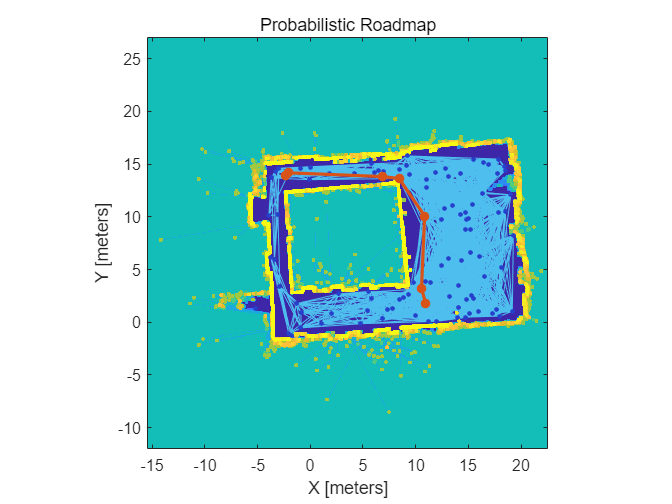

show(prm);

You defined a path following controller above which you can re-use for computing the control commands of a robot on this map. To re-use the controller and redefine the waypoints while keeping the other information the same, use the `release` function.

이 맵에서 로봇의 제어 명령을 계산하는 데 재사용할 수 있는 컨트롤러를 따라가는 경로를 정의했습니다. 컨트롤러를 재사용하고 다른 정보를 동일하게 유지하면서 웨이포인트를 재정의하려면 해제 기능을 사용하십시오.

release(controller);
controller.Waypoints = path;

Set initial location and the goal of the robot as defined by the path

robotInitialLocation = path(1,:);
robotGoal = path(end,:);

Assume an initial robot orientation

initialOrientation = 0;

Define the current pose for robot motion [x y theta]

robotCurrentPose = [robotInitialLocation initialOrientation]';

Compute distance to the goal location 

목표 위치까지의 거리 계산

distanceToGoal = norm(robotInitialLocation - robotGoal);

Define a goal radius

goalRadius = 0.15;

Drive the robot using the controller output on the given map until it reaches the goal. The controller runs at 10 Hz.

목표에 도달할 때까지 주어진 맵의 컨트롤러 출력을 사용하여 로봇을 구동합니다. 컨트롤러는 10Hz에서 실행됩니다

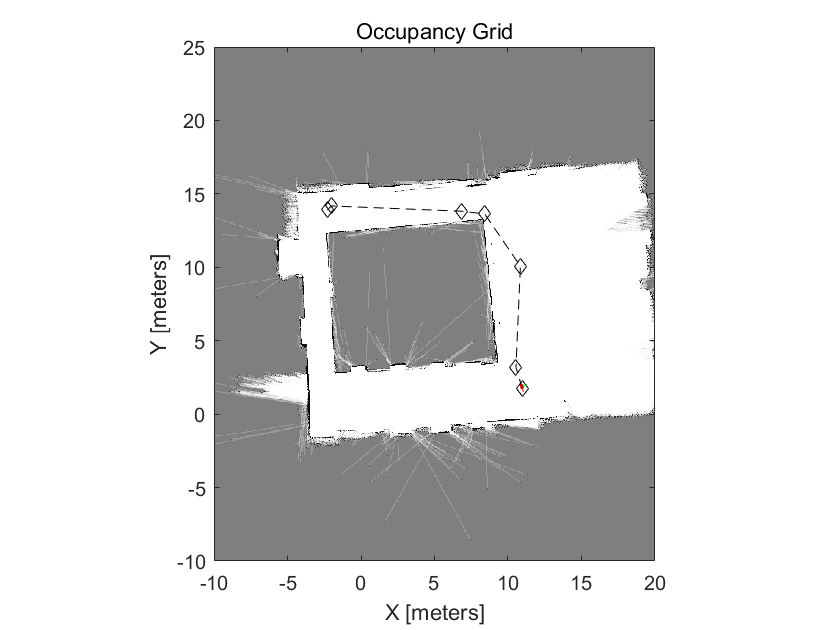

sampleTime = 0.1;
vizRate = rateControl(1/sampleTime);  %->10Hz
frameSize = robot.TrackWidth/0.8;
%위에 중복때문에 주석처리해서 다시 복사해옴

reset(vizRate);

% Initialize the figure
figure

while( distanceToGoal > goalRadius )
    
    % Compute the controller outputs, i.e., the inputs to the robot
    [v, omega] = controller(robotCurrentPose);
    
    % Get the robot's velocity using controller inputs
    vel = derivative(robot, robotCurrentPose, [v omega]);
    
    % Update the current pose
    robotCurrentPose = robotCurrentPose + vel*sampleTime; 
    
    % Re-compute the distance to the goal
    distanceToGoal = norm(robotCurrentPose(1:2) - robotGoal(:));
    
    % Update the plot
    hold off
    show(map);
    hold all

    % Plot path each instance so that it stays persistent while robot mesh
    % moves
    plot(path(:,1), path(:,2),"k--d")
    
    % Plot the path of the robot as a set of transforms
    plotTrVec = [robotCurrentPose(1:2); 0];
    plotRot = axang2quat([0 0 1 robotCurrentPose(3)]);
    plotTransforms(plotTrVec', plotRot, 'MeshFilePath', 'groundvehicle.stl', 'Parent', gca, "View","2D", "FrameSize", frameSize);
    light;
    xlim([-10 20]) %맵에서 안보여서 변경함 다른 지도도 보려면 이거값 수정해야할거임
    ylim([-10 25]) %맵에서 안보여서 변경함 다른 지도도 보려면 이거값 수정해야할거임
    
    waitfor(vizRate);
end

## Model Overview

Open the model.

%open_system('simulateAICENRobotInGazebo.slx')
open_system('simulateAICENATRobotInGazebo2.slx')

The model can be divided into the following elements:

- **Sense:** Read data from sensors in Gazebo.

- **Schedule: **Assign packages and plan paths for robots to deliver the packages.

- **Control:** Generate commands to follow the predefined path and avoid obstacles.

- **Actuate:** Send commands to Gazebo to actuate the robot in the environment.

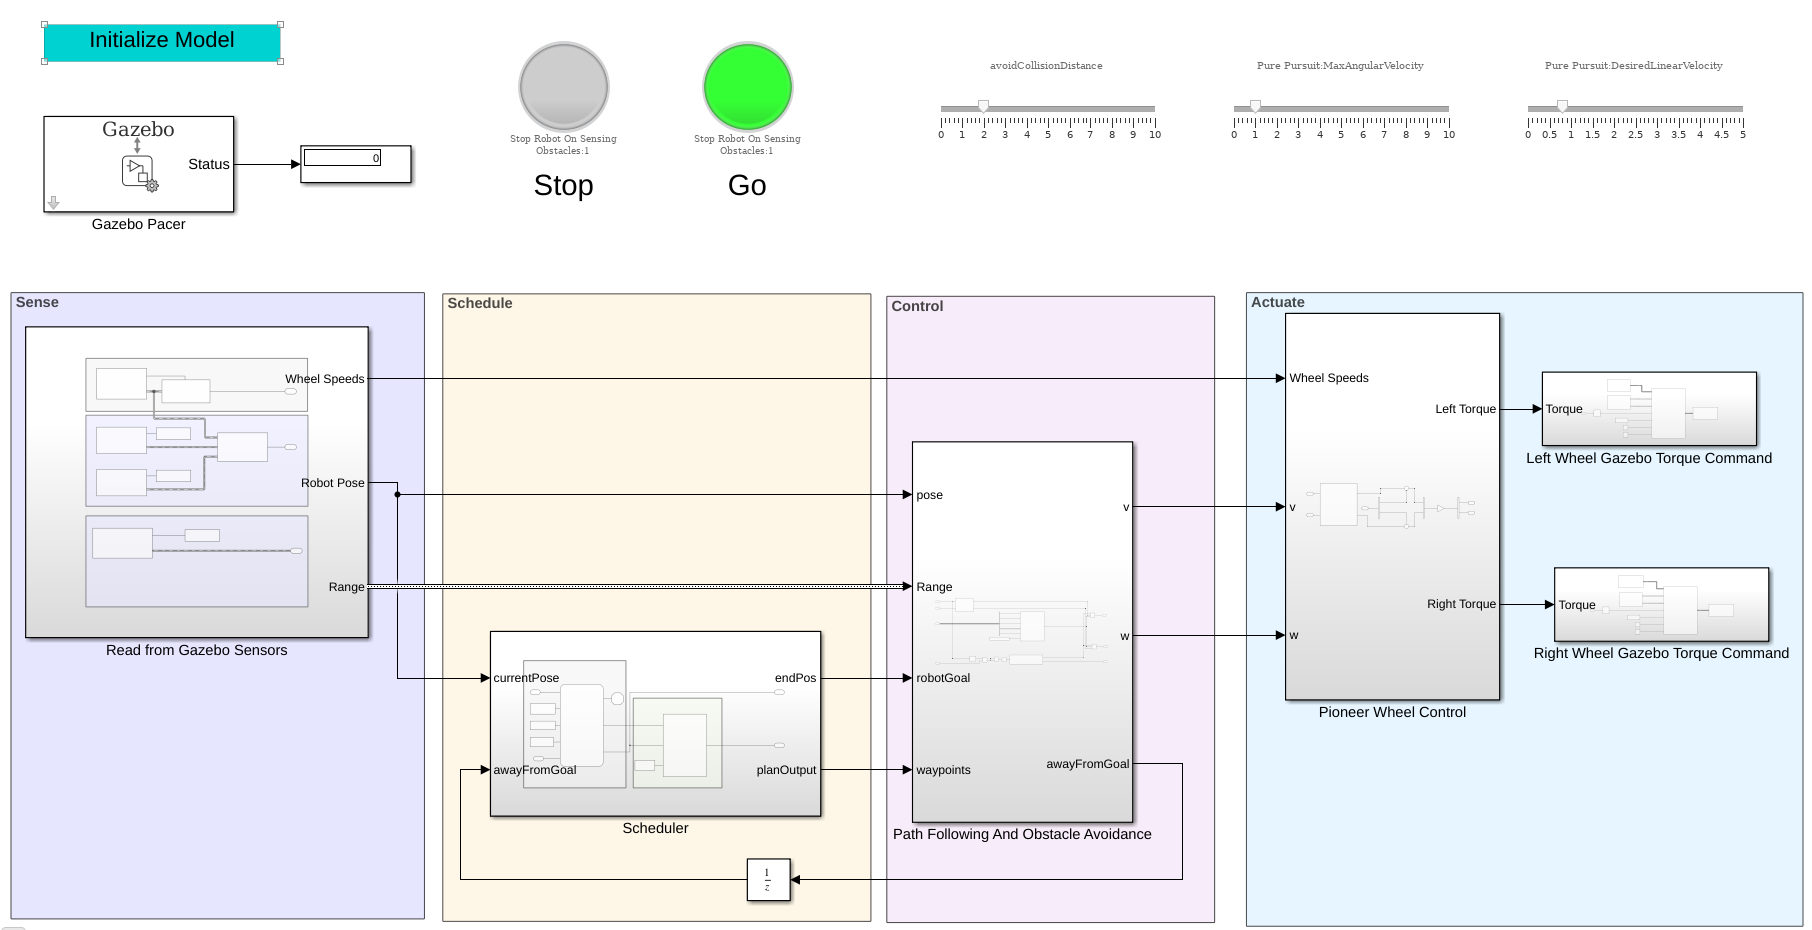

### Schedule

The robot performs the task of going between the charging station, the loading station, and the unloading station as guided by the **Scheduler**.

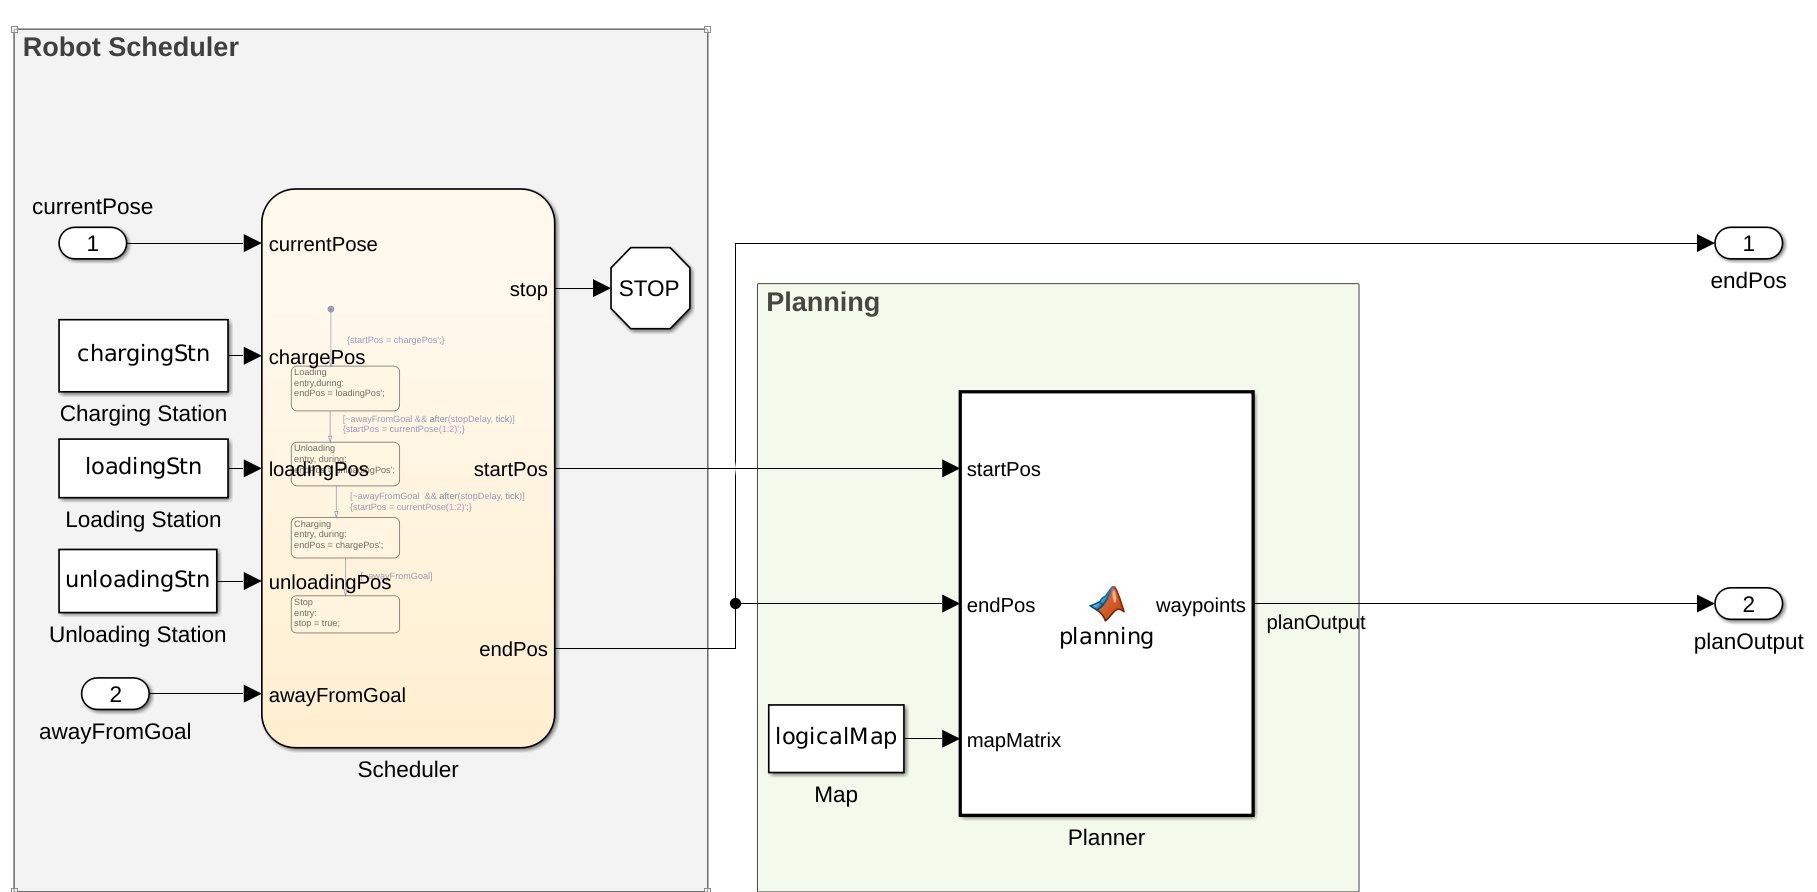

### Sense

The current robot pose, the wheel speeds, and the range sensor readings are read from the simulated environment in Gazebo. The figure below is the expanded view of the **Read From Gazebo Sensors** subsystem.

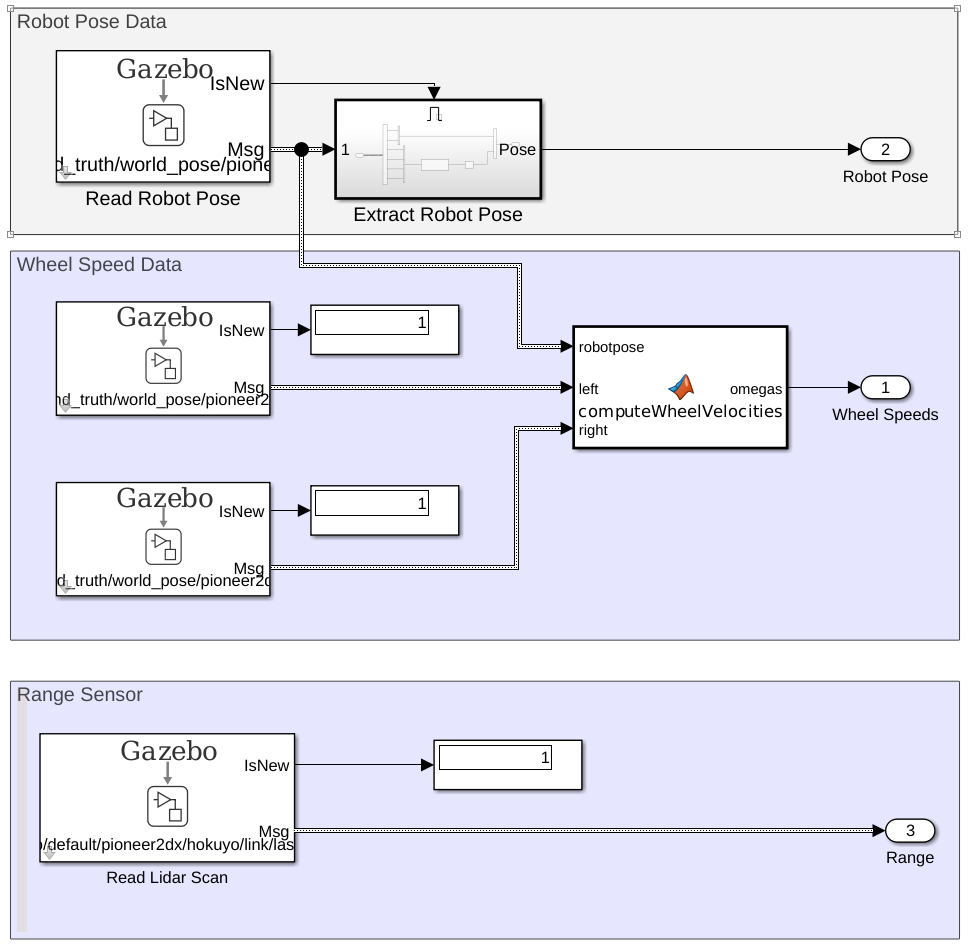

### Control

The controller generates control commands for following the waypoints using the **Pure Pursuit** block. If the range sensor on the robot detects an obstacle within the `avoidCollisionDistance` threshold, the robot stops. Also, the robot stops when gets near enough to the goal.

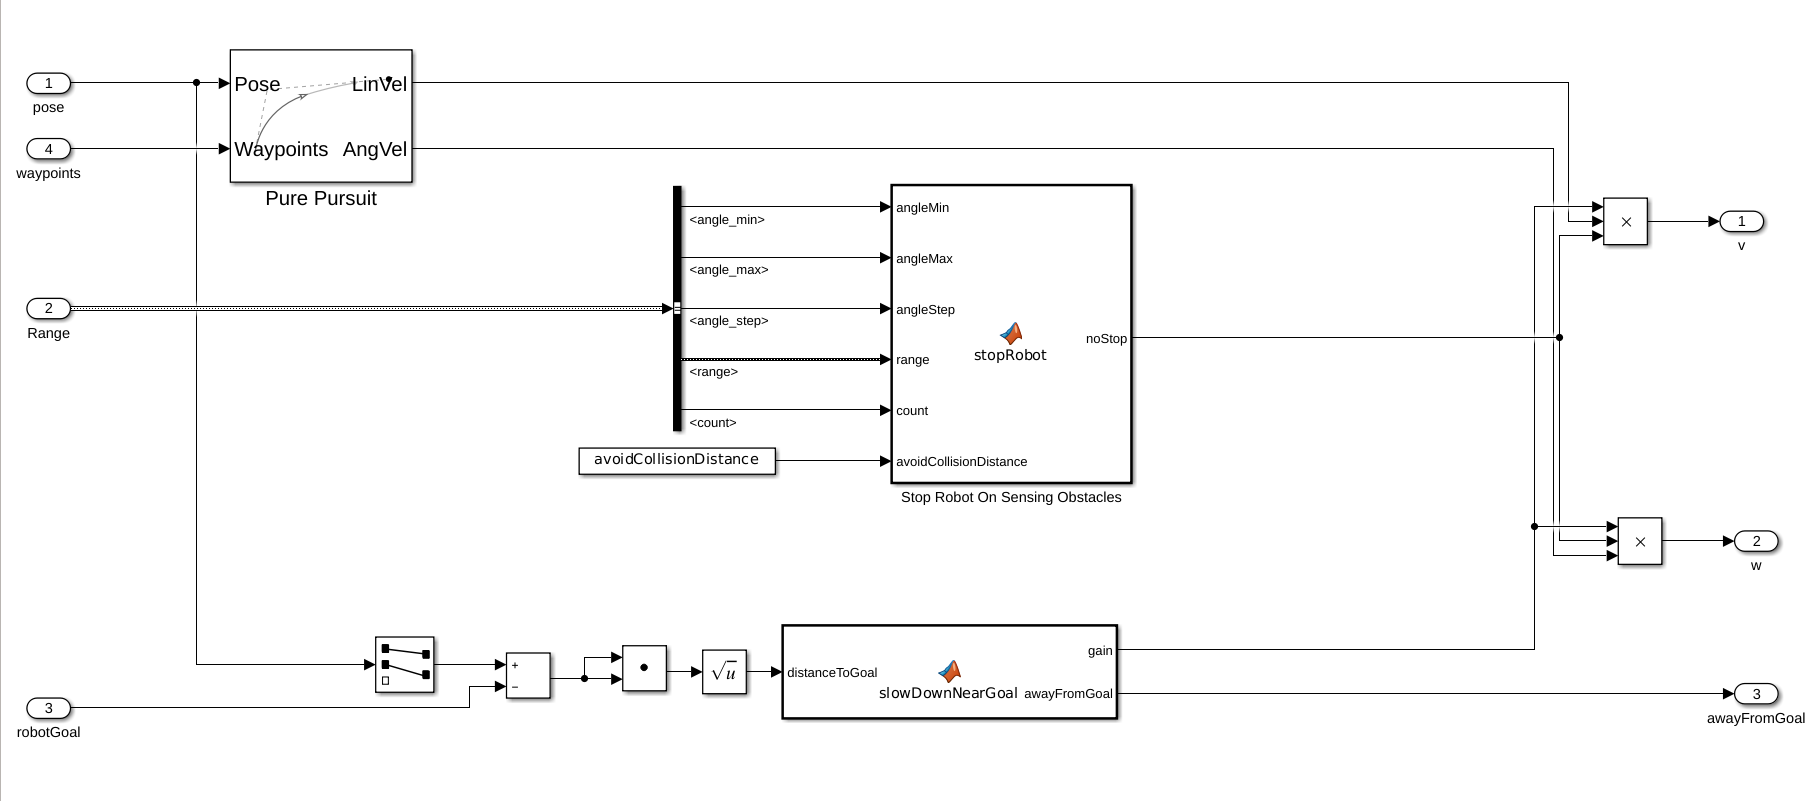

### Actuate

Based on the generated control commands, the **Pioneer Wheel Control** subsystem generates a torque value for each wheel.The torque is applied as an `ApplyJointTorque` command.

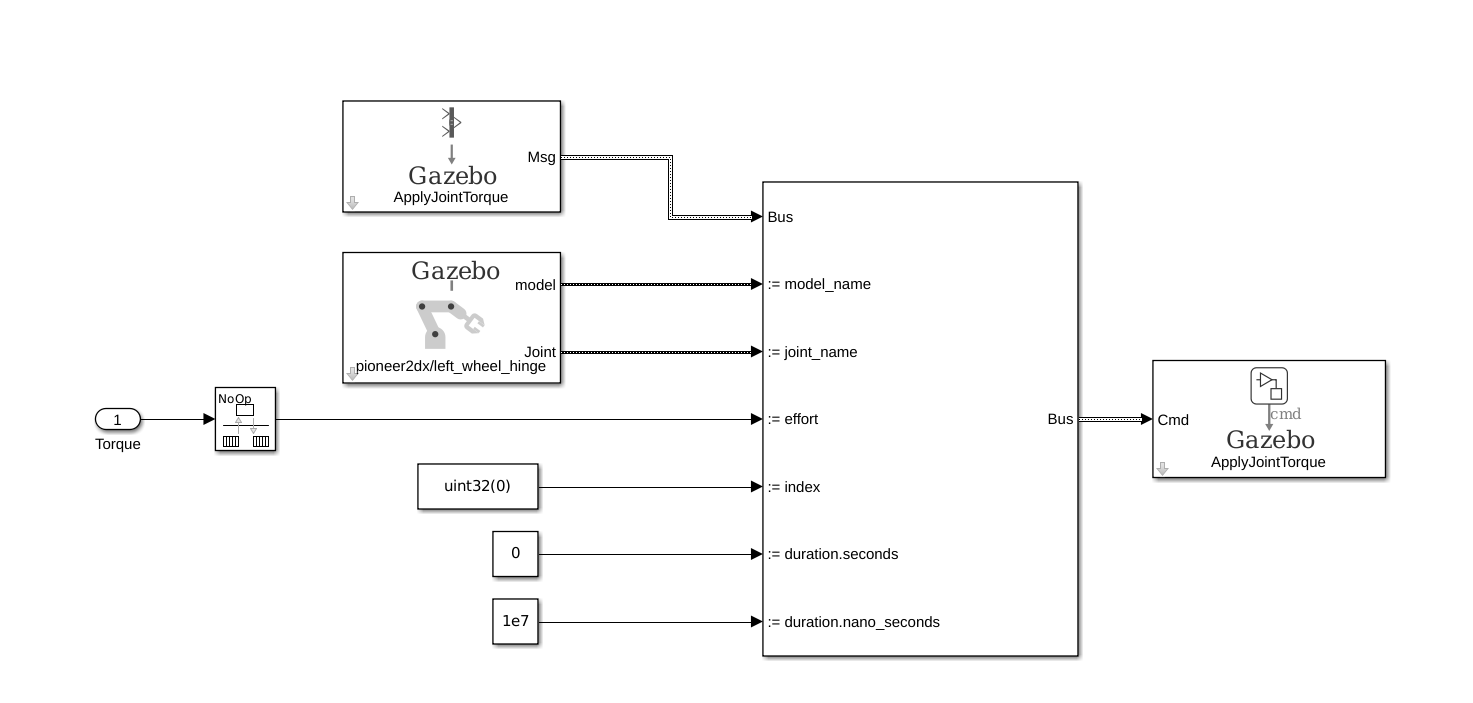

## Setup

### Warehouse Facility

Load the example map file, `map`, which is a matrix of logical values indicating occupied space in the warehouse. Invert this matrix to indicate free space, and make a `binaryOccupancyMap` object. Specify a resolution of 100 cells per meter.

The map is based off of the `warehouseExtensions.world` file, which was made using the Building Editor on the same scaling factor as mentioned below. A `.png` file for the map can be made using the `collision_map_creator_plugin` plugin to generate the map matrix. The details on how to install the plugin can be found at [Collision Map Creator Plugin](http://gazebosim.org/tutorials?tut=custom_messages&cat=transport). 

mapScalingFactor = 100;
load gazeboWarehouseMap.mat map

logicalMap = ~map;
map = binaryOccupancyMap(logicalMap,mapScalingFactor);
show(map)

 Assign the *xy*-locations of the charging station, sorting station, and the unloading location near shelves in the warehouse. The values chosen are based on the simlated world in Gazebo.

% chargingStn = [12,5];
% loadingStn = [24,5];
% unloadingStn = [15,24];

chargingStn = [3,5];
loadingStn = [24,7];
unloadingStn = [5,16.5];

Show the various locations on the map.

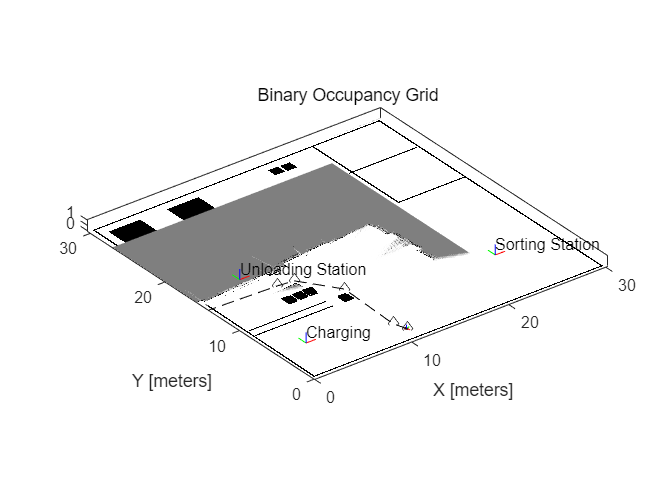

hold on;

text(chargingStn(1), chargingStn(2), 1, 'Charging');
plotTransforms([chargingStn, 0], [1 0 0 0])

text(loadingStn(1), loadingStn(2), 1, 'Sorting Station');
plotTransforms([loadingStn, 0], [1 0 0 0])

text(unloadingStn(1), unloadingStn(2), 1, 'Unloading Station');
plotTransforms([unloadingStn, 0], [1 0 0 0])


%

hold off;

### Range Sensor

The **Read Lidar Scan** block in the Sensing section is used to read the range values from the simulated range sensor. The `warehouseExtensions.world` file contains the details of the various models and actors (warehouse workers) in the scene. Because <`actor>` tags are static links with only visual meshes, the sensor type of the range sensor is `gpu_ray`.

Additionally, the range sensor uses 640 range, but the default is 128. This requires modification of the buses used in the in the **Read Lidar Scan** block. Load the `exampleHelperWarehouseRobotWithGazeboBuses.mat` file to get a modified bus with `Gazebo_SL_Bus_gazebo_msgs_LaserScan.range` set to 640. The modified buses were saved to a `.mat` file using the Bus Editor.

load exampleHelperWarehouseRobotWithGazeboBuses.mat

## Collision Avoidance

The actors in the world are walking a predefined trajectory. The robot makes use of a range sensor to check for obstacles within a range of 2.0 m (`avoidCollisionDistance)`  with range angles from `[-pi/10, pi/10]` Upon a non-zero reading within that range and view, the robot stops and only resumes after the range is clear. The "Stop Robot On Sensing Obstacles" function block incorporates this logic. 

While running the simulation, the **Stop **lamp turns green when the robot senses that it is good to proceed. If it has stopped the lamp turns red. 

avoidCollisionDistance = 2; 

## Simulate 

To simulate the scenario, set up the connection to Gazebo. 

First, run the Gazebo Simulator. In the virtual machine, click the **Gazebo Warehouse Robot **icon. If the Gazebo simulator fails to open, you may need to reinstall the plugin. See **Install Gazebo Plugin** **Manually** in [Perform Co-Simulation between Simulink and Gazebo](docid:robotics_ug.mw_1054c688-ce70-4924-bce3-2c404f798257).

In Simulink, open the **Gazebo Pacer** block and click **Configure Gazebo network and simulation settings**. Specify the **Network Address** as **Custom**,  the **Hostname/IP Address** for your Gazebo simulation, and a **Port** of `14581`, which is the default port for Gazebo. The desktop of the VM displays the IP address.

For more information about connecting to Gazebo to enable co-simulation, see [Perform Co-Simulation between Simulink and Gazebo](docid:robotics_ug.mw_1054c688-ce70-4924-bce3-2c404f798257).

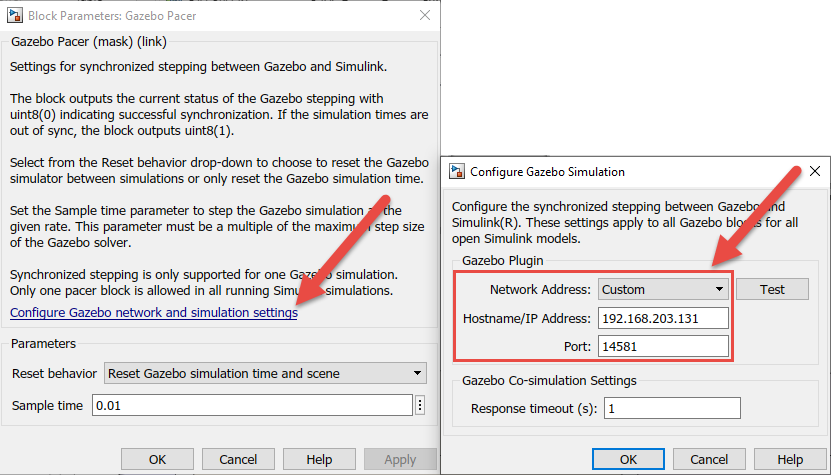

Click the **Initialize Model** button at the top of the model to intialize all the variables declared above. 

**Run** the simulation. The robot drives around the environment and stops whenever a worker gets within the defined threshold. 

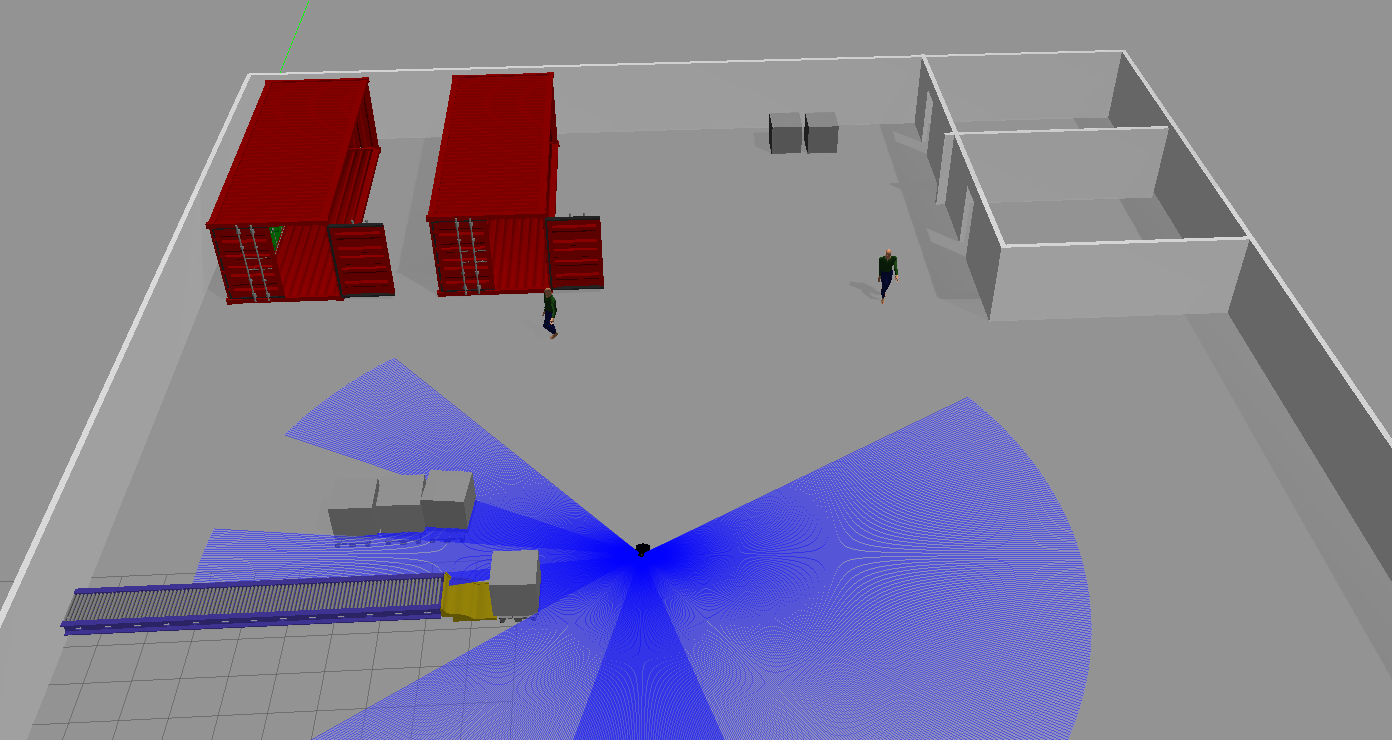

*Copyright 2019 The MathWorks, Inc.*